# Ejercicio 1. I/O y Transformada de Fourier

Realiza un script que importe los datos de un espectro de armónicos almacenado en el fichero "espectroHHG.txt". Filtra los armónicos de orden bajo, y realiza la transformada de Fourier para mostrar cómo los armónicos de orden elevado se emiten en un tren de pulsos de attosegundo. Exporta la emisión temporal en un fichero llamado: "attosHHG.txt"

Compara el resultado con los pulsos que se obtendrían si asumimos que la fase espectral de los armónicos es constante a lo largo del espectro. 

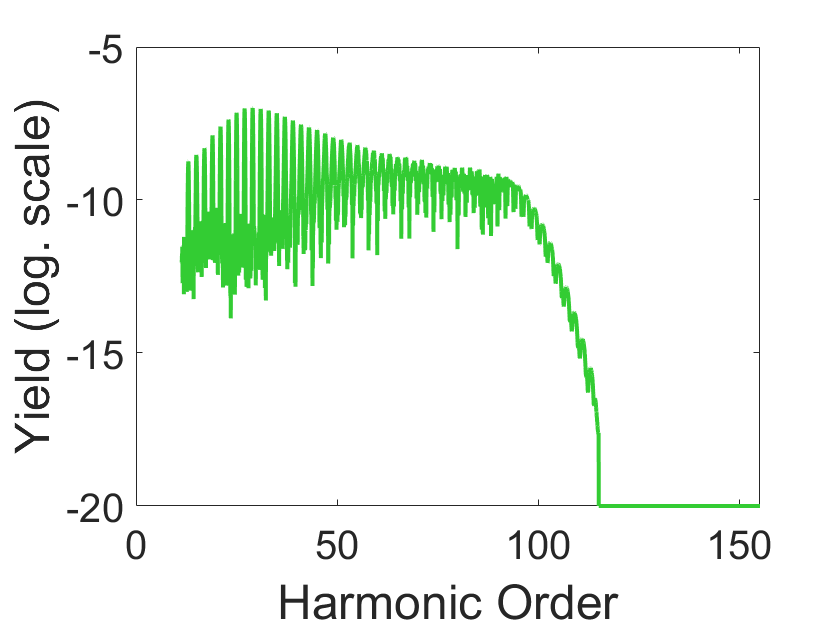

nomFile='espectroHHG.txt';
Esp=importdata(nomFile,' ');
a=Esp(:,1); %Orden armónico
b=Esp(:,2); %Intensidad espectral
c=Esp(:,3); %Fase espectral

limit=300;
b(1:limit)=0; % Hasta el orden del armónico nº20 aprox hacemos nulo el espectro y la fase
c(1:limit)=0;

IU=sqrt(-1);
Spectrum=(sqrt(b).*exp(IU*c)).';
ndt=length(a); 

% Transformada de Fourier del espectro que hemos importado
w0=0.057;
dw=a(2)-a(1); % El paso de las frecuencias
wmax=(a(ndt)+dw)*w0;
t=(0:ndt-1)*2*pi/wmax;
t_period=2*pi/w0;

plot(a,log10(abs(Spectrum).^2), 'Color', [0.2 0.8 0.2], 'LineWidth', 2)
set(gca,'FontSize',20, 'FontName','Avenir');
set(get(gca,'XLabel'),'String','Harmonic Order','FontSize',24,'FontName','Avenir');
set(get(gca,'YLabel'),'String','Yield (log. scale)','FontSize',24,'FontName','Avenir');

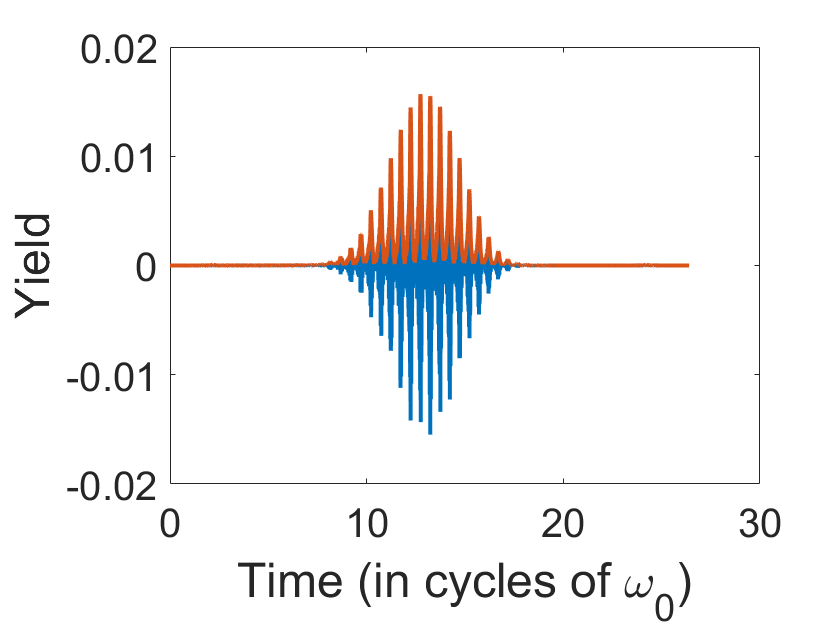


dip=circshift(fft(Spectrum),(ndt/2));
plot(t/t_period, real(dip),  'LineWidth', 2)
hold on
plot(t/t_period, abs(dip),  'LineWidth', 2)
set(gca,'FontSize',20, 'FontName','Avenir')
set(get(gca,'XLabel'),'String','Time (in cycles of \omega_0)','FontSize',24,'FontName','Avenir');
set(get(gca,'YLabel'),'String','Yield','FontSize',24,'FontName','Avenir');
hold off

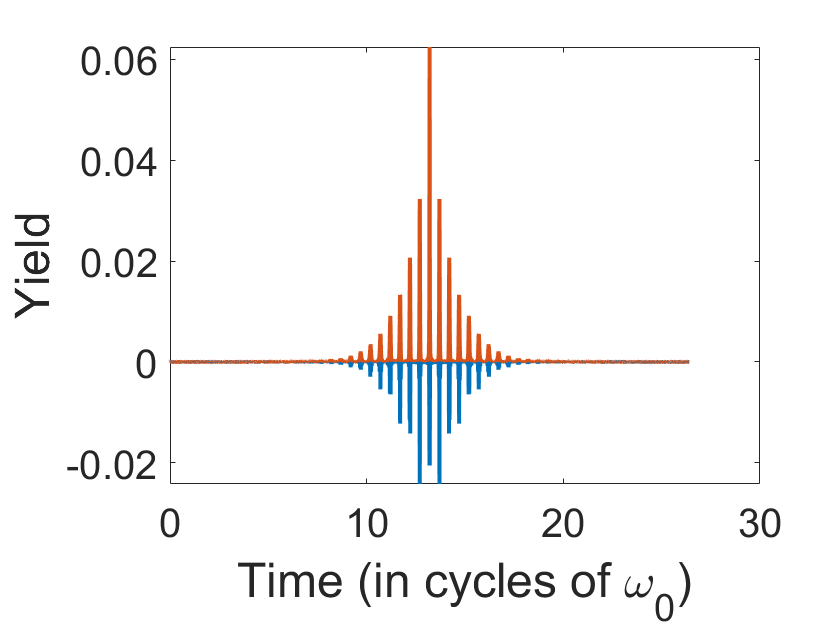


fich=fopen('attosHHG.txt', 'wt+');
% Emisión temporal
for j=1:length(a)
    fprintf(fich, '%e %e %e\n',t(j)/t_period, real(dip(j)), imag(dip(j)));
end
st=fclose(fich);

%Con fase cte: Pulso LT
Spectrum1=(sqrt(b)).';

% Transformada de Fourier del espectro
dip1=circshift(fft(Spectrum1),(ndt/2));
plot(t/t_period, real(dip1),  'LineWidth', 2)
hold on
plot(t/t_period, abs(dip1),  'LineWidth', 2)
set(gca,'FontSize',20, 'FontName','Avenir')
set(get(gca,'XLabel'),'String','Time (in cycles of \omega_0)','FontSize',24,'FontName','Avenir');
set(get(gca,'YLabel'),'String','Yield','FontSize',24,'FontName','Avenir');
hold off

# Ejercicio 2. Interpolación

Si representas la parte real de los pulsos de attosegundo en un intervalo temporal de medio ciclo, podrás observar que la curva no está bien resuelta. Investiga y utiliza las funciones [spline](https://es.mathworks.com/help/matlab/ref/spline.html) o [interp1](https://es.mathworks.com/help/matlab/ref/interp1.html?searchHighlight=interp&s_tid=srchtitle) para interpolar los datos y mostrar una curva más suave.

dip=circshift(fft(Spectrum),(length(t)))

dip =   -0.0004 + 0.0032i   0.0018 + 0.0022i   0.0022 + 0.0004i   0.0018 - 0.0006i   0.0011 - 0.0017i  -0.0004 - 0.0017i  -0.0008 - 0.0011i  -0.0017 - 0.0004i  -0.0009 + 0.0011i  -0.0003 + 0.0004i  -0.0001 + 0.0013i   0.0005 + 0.0004i   0.0009 + 0.0008i   0.0006 - 0.0008i   0.0006 + 0.0001i  -0.0001 - 0.0009i   0.0004 - 0.0005i  -0.0012 - 0.0002i   0.0002 - 0.0005i  -0.0005 + 0.0007i  -0.0010 - 0.0005i   0.0010 + 0.0010i  -0.0010 + 0.0005i   0.0010 - 0.0007i   0.0004 + 0.0014i  -0.0005 - 0.0010i   0.0013 - 0.0003i  -0.0005 + 0.0008i  -0.0006 - 0.0019i   0.0012 + 0.0006i  -0.0022 + 0.0003i   0.0010 - 0.0014i   0.0001 + 0.0021i  -0.0019 - 0.0013i   0.0027 + 0.0009i  -0.0021 + 0.0010i   0.0018 - 0.0022i  -0.0003 + 0.0029i  -0.0007 - 0.0034i   0.0020 + 0.0029i  -0.0028 - 0.0030i   0.0031 + 0.0022i  -0.0040 - 0.0021i   0.0040 + 0.0023i  -0.0042 - 0.0026i   0.0037 + 0.0037i  -0.0029 - 0.0044i   0.0015 + 0.0056i   0.0011 - 0.0059i  -0.0038 + 0.0049i


halfcicle=pi/w0;
t=(0:halfcicle)*2*pi/wmax

t =          0    0.7105    1.4210    2.1314    2.8419    3.5524    4.2629    4.9733    5.6838    6.3943    7.1048    7.8152    8.5257    9.2362    9.9467   10.6571   11.3676   12.0781   12.7886   13.4990   14.2095   14.9200   15.6305   16.3409   17.0514   17.7619   18.4724   19.1828   19.8933   20.6038   21.3143   22.0247   22.7352   23.4457   24.1562   24.8666   25.5771   26.2876   26.9981   27.7085   28.4190   29.1295   29.8400   30.5504   31.2609   31.9714   32.6819   33.3923   34.1028   34.8133


zz=dip(1:56)

zz =   -0.0004 + 0.0032i   0.0018 + 0.0022i   0.0022 + 0.0004i   0.0018 - 0.0006i   0.0011 - 0.0017i  -0.0004 - 0.0017i  -0.0008 - 0.0011i  -0.0017 - 0.0004i  -0.0009 + 0.0011i  -0.0003 + 0.0004i  -0.0001 + 0.0013i   0.0005 + 0.0004i   0.0009 + 0.0008i   0.0006 - 0.0008i   0.0006 + 0.0001i  -0.0001 - 0.0009i   0.0004 - 0.0005i  -0.0012 - 0.0002i   0.0002 - 0.0005i  -0.0005 + 0.0007i  -0.0010 - 0.0005i   0.0010 + 0.0010i  -0.0010 + 0.0005i   0.0010 - 0.0007i   0.0004 + 0.0014i  -0.0005 - 0.0010i   0.0013 - 0.0003i  -0.0005 + 0.0008i  -0.0006 - 0.0019i   0.0012 + 0.0006i  -0.0022 + 0.0003i   0.0010 - 0.0014i   0.0001 + 0.0021i  -0.0019 - 0.0013i   0.0027 + 0.0009i  -0.0021 + 0.0010i   0.0018 - 0.0022i  -0.0003 + 0.0029i  -0.0007 - 0.0034i   0.0020 + 0.0029i  -0.0028 - 0.0030i   0.0031 + 0.0022i  -0.0040 - 0.0021i   0.0040 + 0.0023i  -0.0042 - 0.0026i   0.0037 + 0.0037i  -0.0029 - 0.0044i   0.0015 + 0.0056i   0.0011 - 0.0059i  -0.0038 + 0.0049i


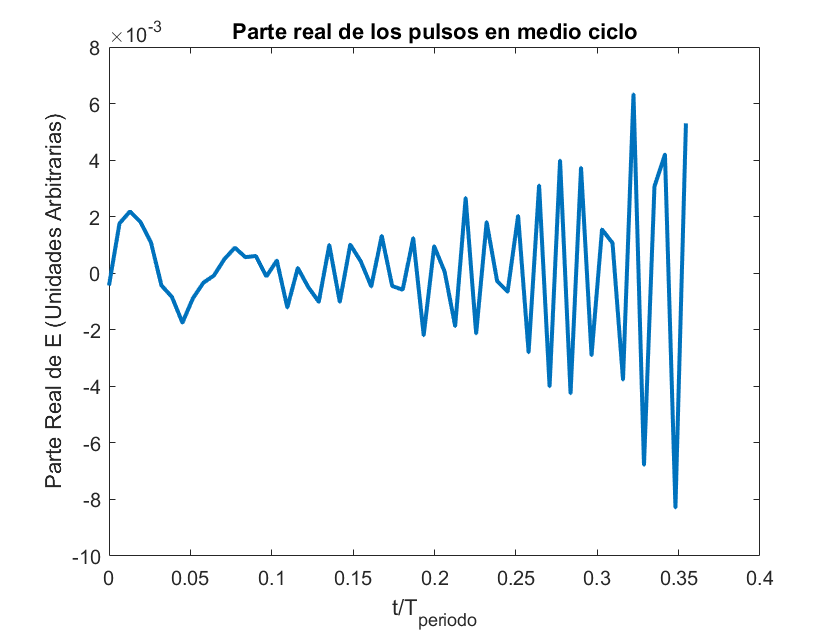

plot(t/t_period, real(zz),  'LineWidth', 2)
title('Parte real de los pulsos en medio ciclo', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel('t/T_{periodo}', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel('Parte Real de E (Unidades Arbitrarias)', 'FontSize', 12, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');


xx = linspace(0,halfcicle*2*pi/wmax,56)

xx =          0    0.7120    1.4239    2.1359    2.8479    3.5598    4.2718    4.9838    5.6958    6.4077    7.1197    7.8317    8.5436    9.2556    9.9676   10.6795   11.3915   12.1035   12.8155   13.5274   14.2394   14.9514   15.6633   16.3753   17.0873   17.7992   18.5112   19.2232   19.9351   20.6471   21.3591   22.0711   22.7830   23.4950   24.2070   24.9189   25.6309   26.3429   27.0548   27.7668   28.4788   29.1908   29.9027   30.6147   31.3267   32.0386   32.7506   33.4626   34.1745   34.8865


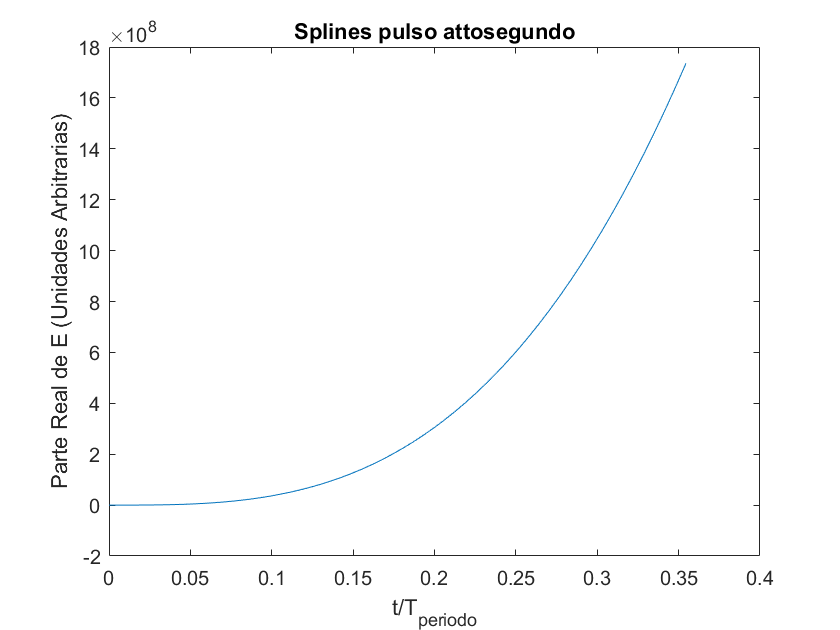

y=spline(t/t_period,real(zz),xx);
plot(t/t_period,y)
title('Splines pulso attosegundo', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel('t/T_{periodo}', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel('Parte Real de E (Unidades Arbitrarias)', 'FontSize', 12, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');